% generate some fake data
x = (rand(1,100).^2) +20;

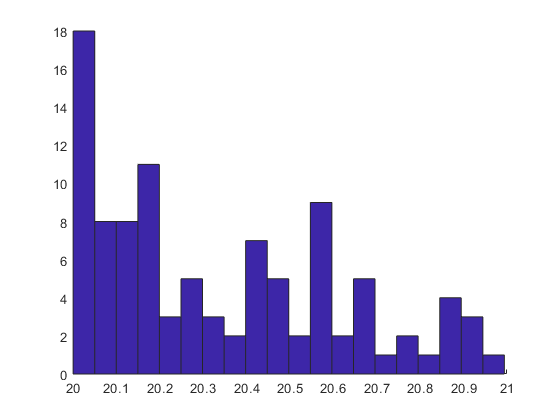

%compute some simple data summary deviation

mn = mean(x); % compute mean
sd = std(x); % compute standard deviation
ptiles = prctile(x,[15 60 84]);


% make a figure

figure;
hold on;
hist(x,20); % plot a histgram using twent bins

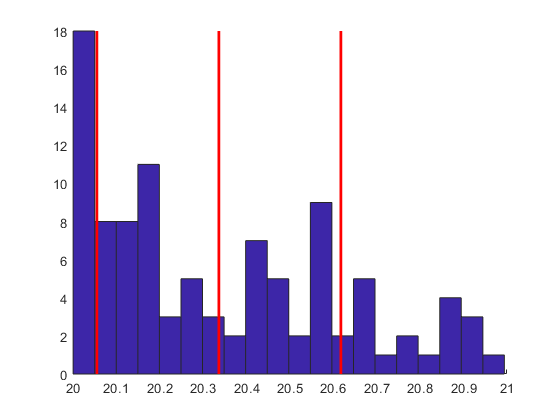

ax = axis; % get the current axis bounds
        %plot lines showing mean and +/- std dev
h1 = plot([mn mn], ax(3:4), 'r-', 'LineWidth',2);
h2 = plot([mn-sd mn-sd], ax(3:4), 'r-', 'LineWidth',2);
h3 = plot([mn+sd mn+sd], ax(3:4), 'r-', 'LineWidth',2);

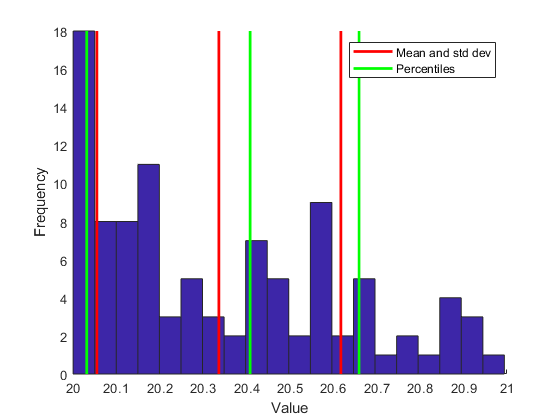


% plot lines showing percentiles
h4 = [];

for p=1:length(ptiles)
    h4(p) = plot(repmat(ptiles(p), [1 2]), ax(3:4),'g-','LineWidth',2);
end

legend([h1 h4(1)], {'Mean and std dev' 'Percentiles'});
xlabel('Value');
ylabel('Frequency');